## Load Data

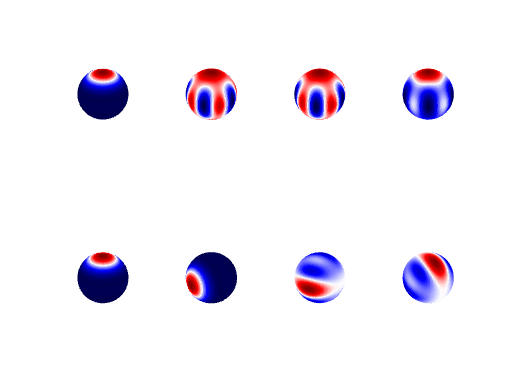

clear all;
close all;
f=figure;

tiledlayout(2,4)
nexttile;
load("initial.mat");
wigner_plot_only_fun(wigner_result);

nexttile;
load('cat.mat');
wigner_plot_only_fun(wigner_result);

nexttile;
load("precess_cat.mat");
wigner_plot_only_fun(wigner_result);

nexttile;
load("detect_cat.mat");
wigner_plot_only_fun(wigner_result);

nexttile;
load("initial.mat");
wigner_plot_only_fun(wigner_result);

nexttile;
load('coherent.mat');
wigner_plot_only_fun(wigner_result);

nexttile;
load("precess_mix.mat");
wigner_plot_only_fun(wigner_result);

nexttile;
load("detect_mix.mat");
wigner_plot_only_fun(wigner_result);

savefig(f,'\\Edm-heracles\e\WignerFunction.fig');

function wigner_plot_only_fun(wigner_result)
    [m,n]=size(wigner_result);
    theta_list=[0:pi/(m-1):pi];
    phi_list=[0:2*pi/(n-1):2*pi]-pi/2;
    %f1=figure;
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,real(wigner_result));
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    %caxis([-1 1]);
    xlabel('x');
    ylabel('y');
    %view([0 90]);
    %set(f1,"Visible","On");
    daspect([1 1 1]);
    %axis equal;
    set(surf,"LineStyle","none", "FaceColor","texturemap",...
        "FaceLighting","gouraud");
    colorbar('off');
    box off;
    axis off;
    cMap=getPyPlot_cMap('seismic');
    colormap(cMap);
end